# A Basic SISO Example.

Given the uncertain plant, defined in real factored form with parametric uncertainty


$$\begin{array}{l}
P\left(s\right)=k\frac{s+a}{1+2\zeta \text{ }s/\omega {\text{ }}_{n\text{ }} +s^{2\text{ }} /{\omega \text{ }}_n^2 },\text{ }\\
k\in \left\lbrack 2,5\right\rbrack ,\text{ }\text{ }\text{ }a\in \left\lbrack 1,3\right\rbrack ,\text{  }\zeta \in \left\lbrack 0\ldotp 1,0\ldotp 6\right\rbrack ,\text{  }\omega {\text{ }}_{n\text{ }} \in \left\lbrack 4,8\right\rbrack ,\text{ }
\end{array}$$
 

close the loop with a feedback compensator $G\left(s\right)$, and a prefilter $F\left(s\right)\text{ }$such that the following specifications are satisfied:

- 
$$M\le 10%$$
 

- $t_{s\text{ }} \le 1\ldotp 5$ sec.

- $S\left(j\omega \text{ }\right)=|1/\left(1+L\left(j\omega \text{ }\right)\right)|\le 6$ dB

## Plant Definition

In the new object oriented QFT toolbox the plant is defined in an m-file or by the command line as

k=qpar('k',2,2,5,8);        
a=qpar('a',3,1,3,8);
z=qpar('z',0.6,0.3,0.6,8);
wn=qpar('wn',4,4,8,8);

num = [k*wn*wn k*wn*wn*a]; 
den = [1 2*z*wn wn*wn];
P = qplant(num,den);

Each of the uncertain parameters is defined as a `qpar` object. A qpar object such as `k` is defined using the syntex

`par = qpar(name,nom,lbnd,ubnd,cases)`. 

where `name` is a string; `nom`, `lbnd`, `ubnd` are scalaric numbers describing the nominl value, lower bound, and upper bound, respectively; `cases` is an optional input agrument which specifies the number of uncertain cases, i.e. the number of grid points. For exmaple

k = qpar('k',2,2,5,8)

k =   qpar with properties:

           name: 'k'
        nominal: 2
          lower: 2
          upper: 5
          cases: 8
       discrete: []
    description: []


Two or more `qpar` objects can be combined together into a `qexpression`, which stores the parametric description along with a list of all envolded `qpar` objects. For exmaple

exp = k*wn*wn

exp =   qexpression with properties:

    expression: '(k * wn) * wn'
          pars: [2×1 qpar]


The numerator an denomenator are defined using a raw vector of qpar, qexpression, or numeric objects. The first element is the n-order coefficient and so on. The result is a `qpoly` element with all coefficients and parameters

den = [1 2*z*wn wn*wn]

den = qpoly with coefficients

    s2: 1
    s1: '(2 * z) * wn'
    s0: 'wn * wn'


Finally, P is an instance of a `qplant` class, defined by two `qpoly` elemetns definning the numerator and denomenator.

P = qplant(num,den)

P =   qplant with properties:

          num: [1×1 qpoly]
          den: [1×1 qpoly]
         pars: [4×1 qpar]
     unstruct: []
       uncint: []
         info: 'generated from [num,den] data on: 21-Apr-2020 22:32:11'
    templates: [0×0 qtpl]
      nominal: [0×0 qfr]
        delay: []


Note that the preperties 'templates' and 'nominal' are empty. They require computation. The nominal case is computed by the command `cnom `as follows

w_nom = logspace(-2,2,200);
P.cnom(w_nom)

ans =   qplant with properties:

          num: [1×1 qpoly]
          den: [1×1 qpoly]
         pars: [4×1 qpar]
     unstruct: []
       uncint: []
         info: 'generated from [num,den] data on: 21-Apr-2020 22:32:11'
    templates: [0×0 qtpl]
      nominal: [1×1 qfr]
        delay: []


The nominal case that is computed is a `qfr` object. It behaves very simailarly to Matlab's LTI object. For exmaple, a Bode plot is drawn by

ans =   1×2 Axes array:

    Axes    Axes


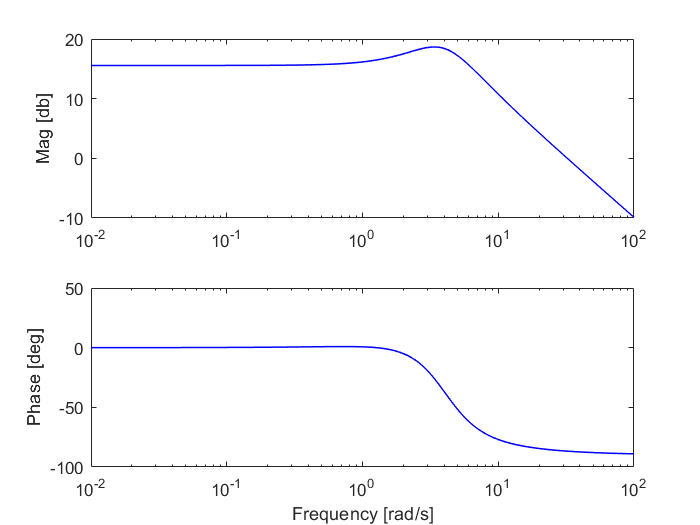

figure, P.nominal.bode()

If one wishes to plot other cases (not the noiminal), the commands `bodcases` and `niccases` are useful. For exmaple, to plot the Bode for uniform grid of parameter cases

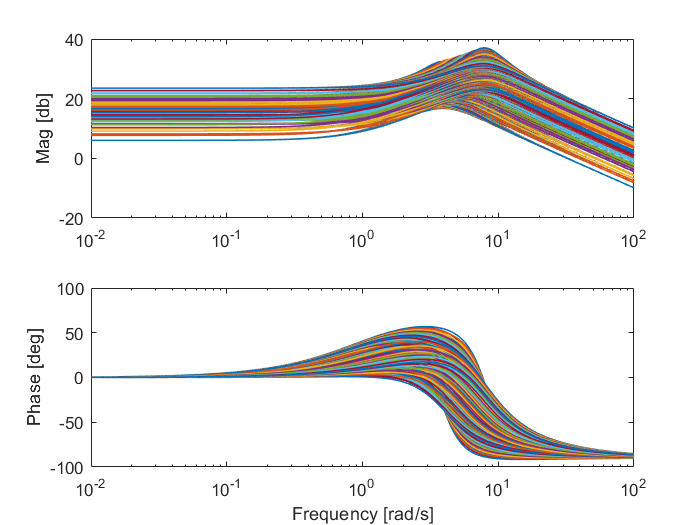

figure, P.bodcases()

A specific set of cases is shown by

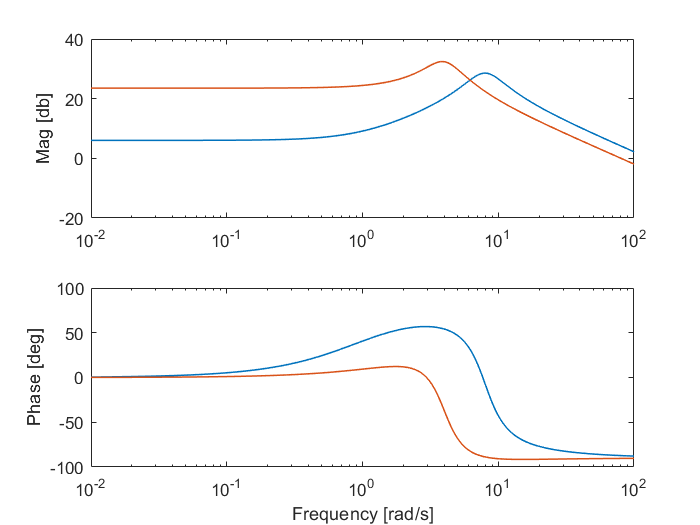

pars = [1 3; 2 5; 8 4; 0.3 0.3];
figure, P.bodcases(pars)

## Template Computation

The templates are computed using `ctpl`. To compute using recurcive edge grid `(`'recedge'`) `at selected frequencies and show them in figure,

w = [0.2 0.5 1 3 5 7 10 20 50];
P.ctpl('recedge',w)

Calculating templates by recurcive edge grid
--> for w=0.2 [rad/s] 
--> for w=0.5 [rad/s] 
--> for w=1 [rad/s] 
--> for w=3 [rad/s] 
PRUNE: Phase uncertainty larger than 360, or not connected
--> for w=5 [rad/s] 
PRUNE: Phase uncertainty larger than 360, or not connected
--> for w=7 [rad/s] 
PRUNE: Phase uncertainty larger than 360, or not connected
--> for w=10 [rad/s] 
PRUNE: Phase uncertainty larger than 360, or not connected
--> for w=20 [rad/s] 
PRUNE: Phase uncertainty larger than 360, or not connected
--> for w=50 [rad/s] 


ans =   qplant with properties:

          num: [1×1 qpoly]
          den: [1×1 qpoly]
         pars: [4×1 qpar]
     unstruct: []
       uncint: []
         info: 'generated from [num,den] data on: 21-Apr-2020 22:32:11'
    templates: [9×1 qtpl]
      nominal: [1×1 qfr]
        delay: []


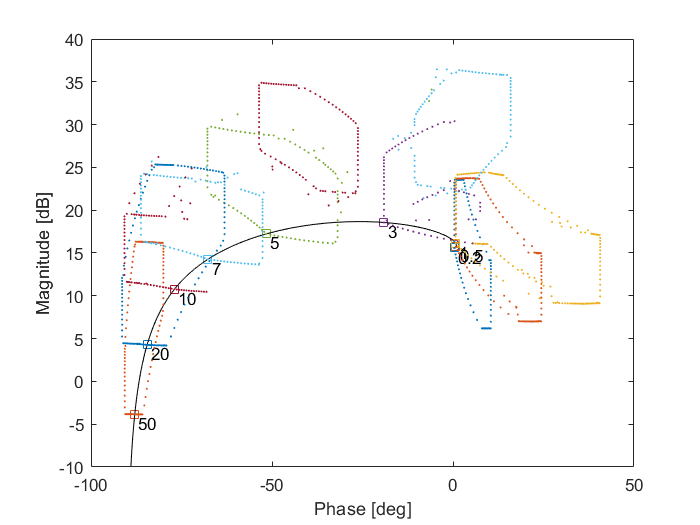

P.showtpl()

Note that the selection of frequencies is crutial to a successfull design. The designer should choose the frequecies such the behaviour of the uncertain plant is covered.

## Specifications

It is now time for the specifications. The 6dB sensitivity specs. are defined as a `qsps` object 

spec1 = qspc('odsrs',w,6)

spec1 =   qspc with properties:

         name: 'odsrs'
    frequency: [0.2000 0.5000 1 3 5 7 10 20 50]
        upper: [6 6 6 6 6 6 6 6 6]
        lower: []
      timespc: []
      timeres: []


The servo specifications are defined by

Creating array of size 4x6000
Reducing to 4x2916
Reducing to 4x2286
Reducing to 4x1547
Reducing to 4x1216
Reducing to 4x983
Reducing to 4x974
Reducing to 4x960
Number of good step-responses: 960


spec2 =   qspc with properties:

         name: 'rsrs'
    frequency: [50×1 double]
        upper: [50×1 double]
        lower: [50×1 double]
      timespc: [8×3 double]
      timeres: [109×3 double]


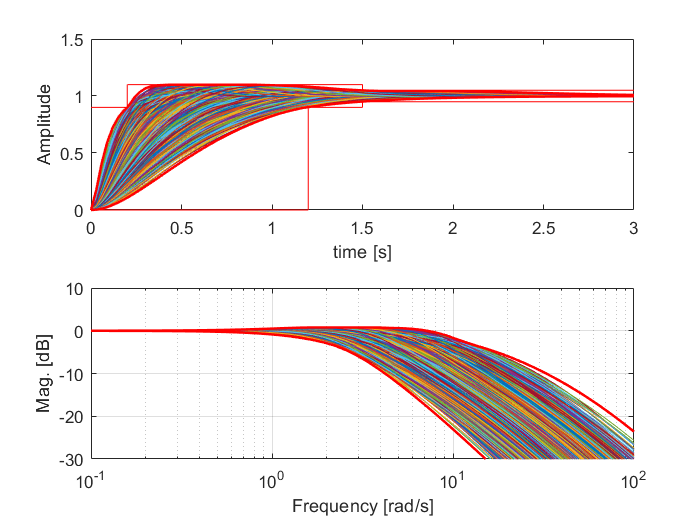

spec2 = qspc.rsrs([1.2 0.2],10,1.5,[],logspace(-1,2),2.85,3.1)

which does the translation from time-domain to frequency domain. The two computed specs. can be shown using the command `show`. For example 

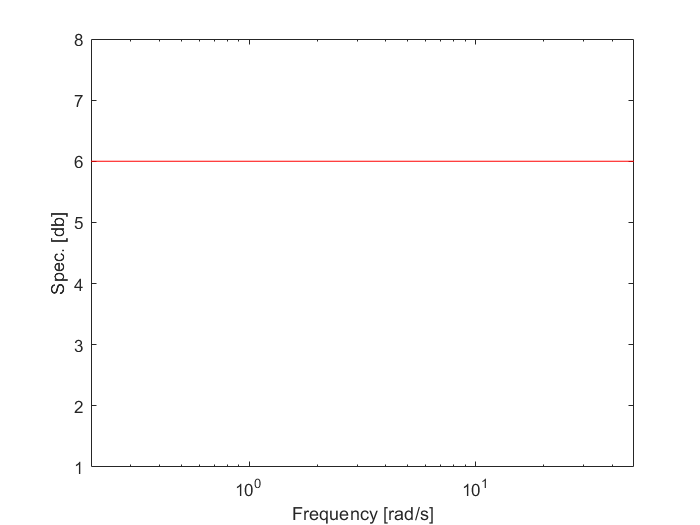

spec1.show();

## Horowitz-Sidi bounds computation

With the templates and frequency domain specifications we can now compute the Horowitz-Sidi (H-S) bounds. First we create a `qdesign` object which will facilitates the bounds creation and loop shaping design. The bounds can than be computed using the command `cbnd(spcname)` with the specification name. The bounds are shown by `showbnd(spcname)`.

For the sensitivity specification:

des = qdesign(P,[spec1 spec2])

You now have a QFT loop desgin object. Compute bounds using CBND


des =   qdesign with properties:

    tpl: [9×1 qtpl]
    nom: [1×1 qfr]
    spc: [1×2 qspc]
    bnd: []
    col: [9×3 double]


des.cbnd('odsrs')

Calculating bounds for odsrs 
--> w(1) = 0.2 [rad/s]
--> w(2) = 0.5 [rad/s]
--> w(3) = 1 [rad/s]
--> w(4) = 3 [rad/s]
--> w(5) = 5 [rad/s]
--> w(6) = 7 [rad/s]
--> w(7) = 10 [rad/s]
--> w(8) = 20 [rad/s]
--> w(9) = 50 [rad/s]


ans =   qdesign with properties:

    tpl: [9×1 qtpl]
    nom: [1×1 qfr]
    spc: [1×2 qspc]
    bnd: [1×1 struct]
    col: [9×3 double]


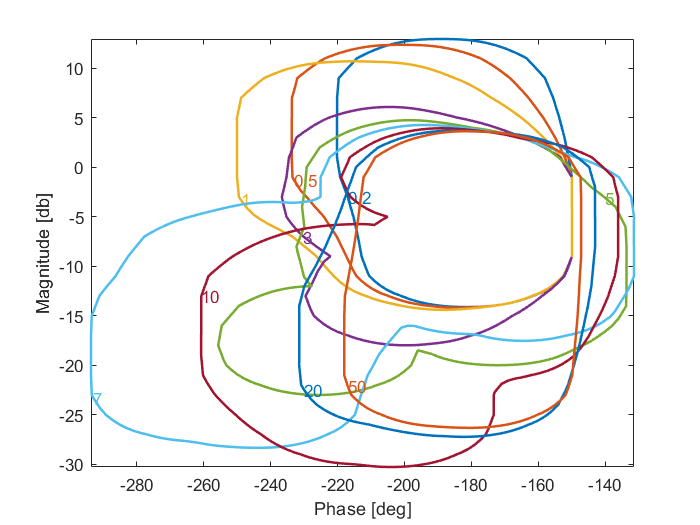

des.showbnd('odsrs')

Similarly for the servo specifications:

des.cbnd('rsrs')

Calculating bounds for rsrs 
--> w(1) = 0.2 [rad/s]
--> w(2) = 0.5 [rad/s]
--> w(3) = 1 [rad/s]
--> w(4) = 3 [rad/s]
--> w(5) = 5 [rad/s]
--> w(6) = 7 [rad/s]
--> w(7) = 10 [rad/s]
--> w(8) = 20 [rad/s]
--> w(9) = 50 [rad/s]


ans =   qdesign with properties:

    tpl: [9×1 qtpl]
    nom: [1×1 qfr]
    spc: [1×2 qspc]
    bnd: [1×2 struct]
    col: [9×3 double]


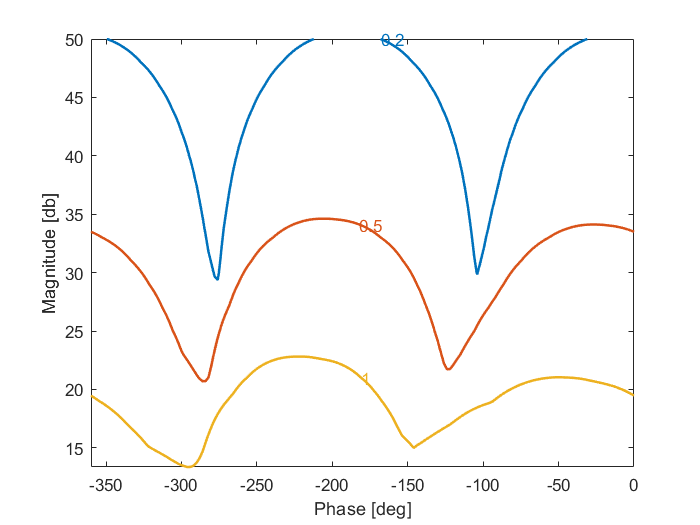

des.showbnd('rsrs')

## Loop Shaping

Now we can do loop shaping! 

We use `showbnd` to plot the dominant bounds. Note the use of the figure handle `h` to show all bounds on the same chart.  The feedback compensator can be defined by e.g. `zpk` from the Control Systems Toolbox.

h = des.showbnd('odsrs',[],[3 5 7 10 20 50]);
des.showbnd('rsrs',h,[0.2 0.5 1]);

% define the compensator G(s):
s = zpk(0,[],1);
set(s,'DisplayFormat','Frequency')
G = 2.5*(1+s/5)*(1+2*0.6*s/4+s^2/16)/s/(1+s)/(1+s/3.2)/(1+s/26)


G =
 
  2.5 (1+s/5) (1 + 1.2(s/4) + (s/4)^2)
  ------------------------------------
       s (1+s) (1+s/3.2) (1+s/26)
 
Continuous-time zero/pole/gain model.



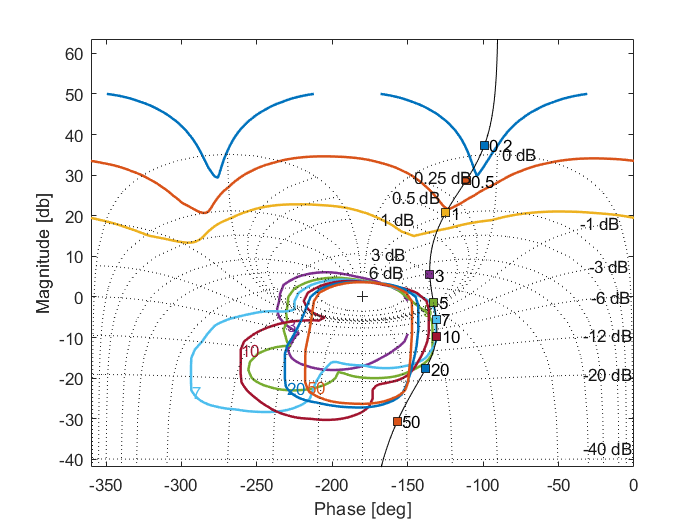


des.loopnic(G) % plot G*Pnom on NC 
ngrid

Note that each frequency has a dedicated color in which the bound and nominal point are drawn

## Prefilter

The prefilter is now designed. To view the closed loop time response with $F\left(s\right)=1$, the command `clmag(G,1)` is used 

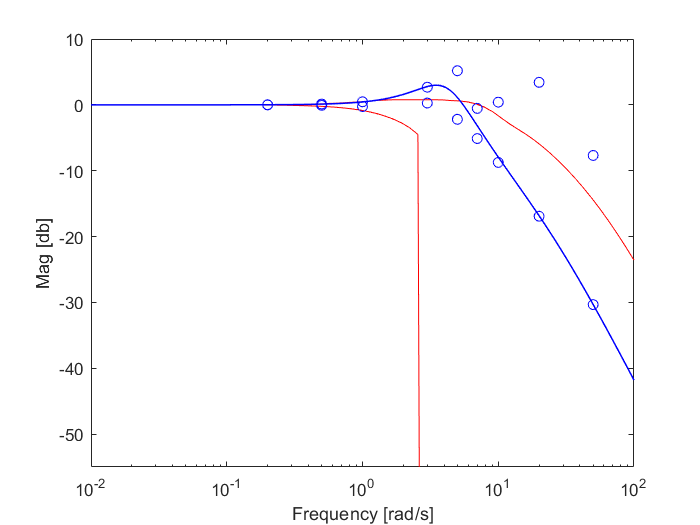

spec2.show('freq');
des.clmag(G,1)
ylim([-55 10])

With a properly designed $F\left(s\right)$  we have

F = 1/(1+2*0.83*s/3.4+s^2/3.4^2)


F =
 
                1
  -----------------------------
  (1 + 1.66(s/3.4) + (s/3.4)^2)
 
Continuous-time zero/pole/gain model.



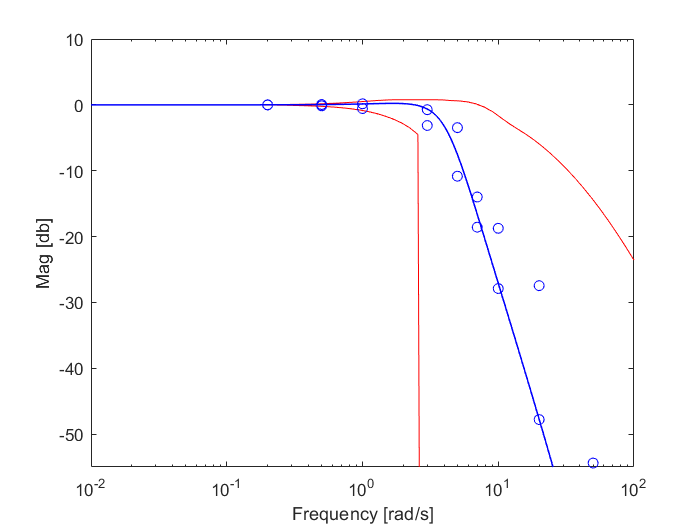

spec2.show('freq');
des.clmag(G,F)
ylim([-55 10])

## Design Validaion 

It is now the time to check if specifications are truely met. The tool for that job is the `qsys` object. We compute qsys object of the open and closed loops 

L = series(P,G);     % open loop
S = feedback(L,1);   % closed loop from d to y (sensitivity)
T = series(S,series(L,F));     % closed loop from r to y

Sensitivity specification can now be checked by

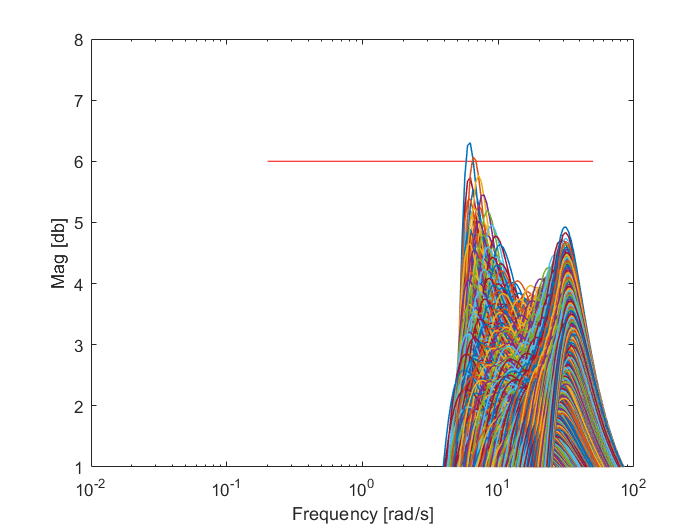

spec1.show; hold on                     % show the specs.
pgrid = P.pars.sample(100);             % generates 20 random samples
S.bodcases([],w_nom,'showphase',0)   % plot magnitude response
xlim([0.01 100])

 Similarly, servo spesification are validated by

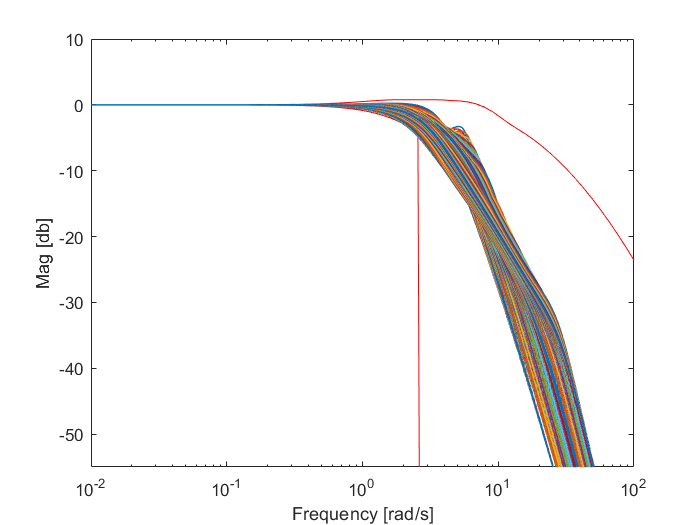

spec2.show('freq'); hold on             % show the specs.
T.bodcases([],w_nom,'showphase',0)   % plot magnitude response
axis([0.01 100 -55 10])

One may see that the specsification are not fully met. One should try and repeat the design with a refined frequency selection around 6 rad/s. We leave that part as an exercise to te user.